# Load data

clc; clear; close all;

dir = [cd '/'];
load('Fall'); % Load Suite2P data

## Parameters

frame_num =size (F, 2);
Int =175; %frame interval of stimulation

## Calculate dF/F of each neuron. ROIs were determined by suite2P algorithm.

[sROI] = stat;
mean_dF= zeros(size(sROI, 2), frame_num);
for cell_num = 1: size(sROI, 2);
    F0(cell_num, :) = mean(F(cell_num, :));
    mean_dF(cell_num, :) =(F(cell_num, :) - F0(cell_num, :))./F0(cell_num, :) ;
end

## Average of 5 stimulation sessions

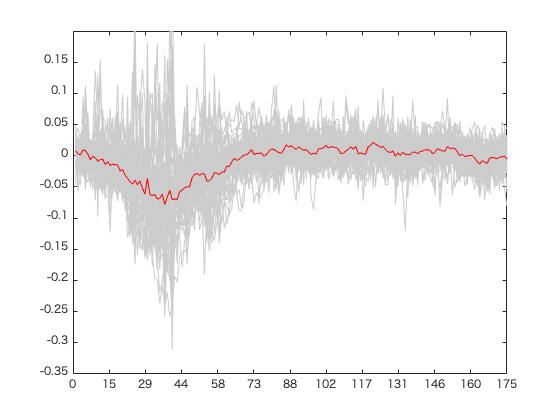

clf
for cell_number=1:cell_num
    for i=1:5
     mean_summary(i,:) = mean_dF(cell_number,Int*i-18:Int*(i+1)-17);
    end
  mean_mean_summary(cell_number,:)= mean(mean_summary.', 2);
end
figure; 
plot(transpose(mean_mean_summary), 'color', [0.8 0.8 0.8] ); hold on;
plot(mean(mean_mean_summary.', 2,"omitnan"),'r'); hold on;
ylim([-0.35 0.20])
xlim([0 Int])
xticks(0:Int/12:Int);
xtickformat('%.0f');